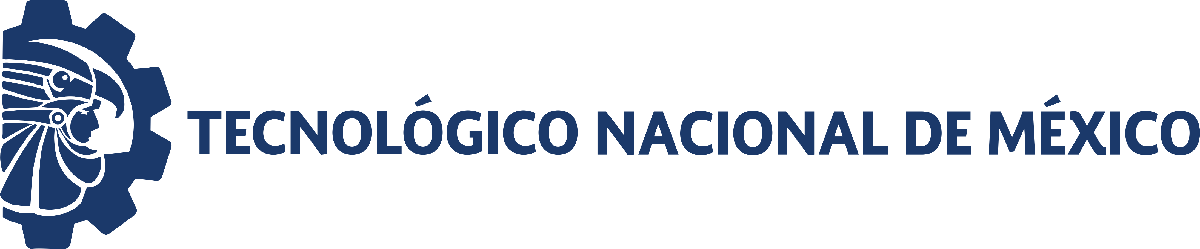                                 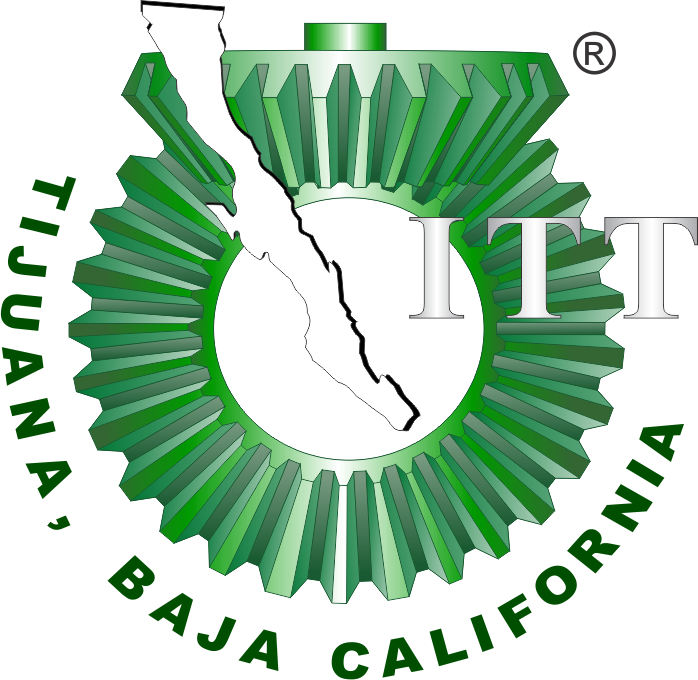

# Práctica 5.3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

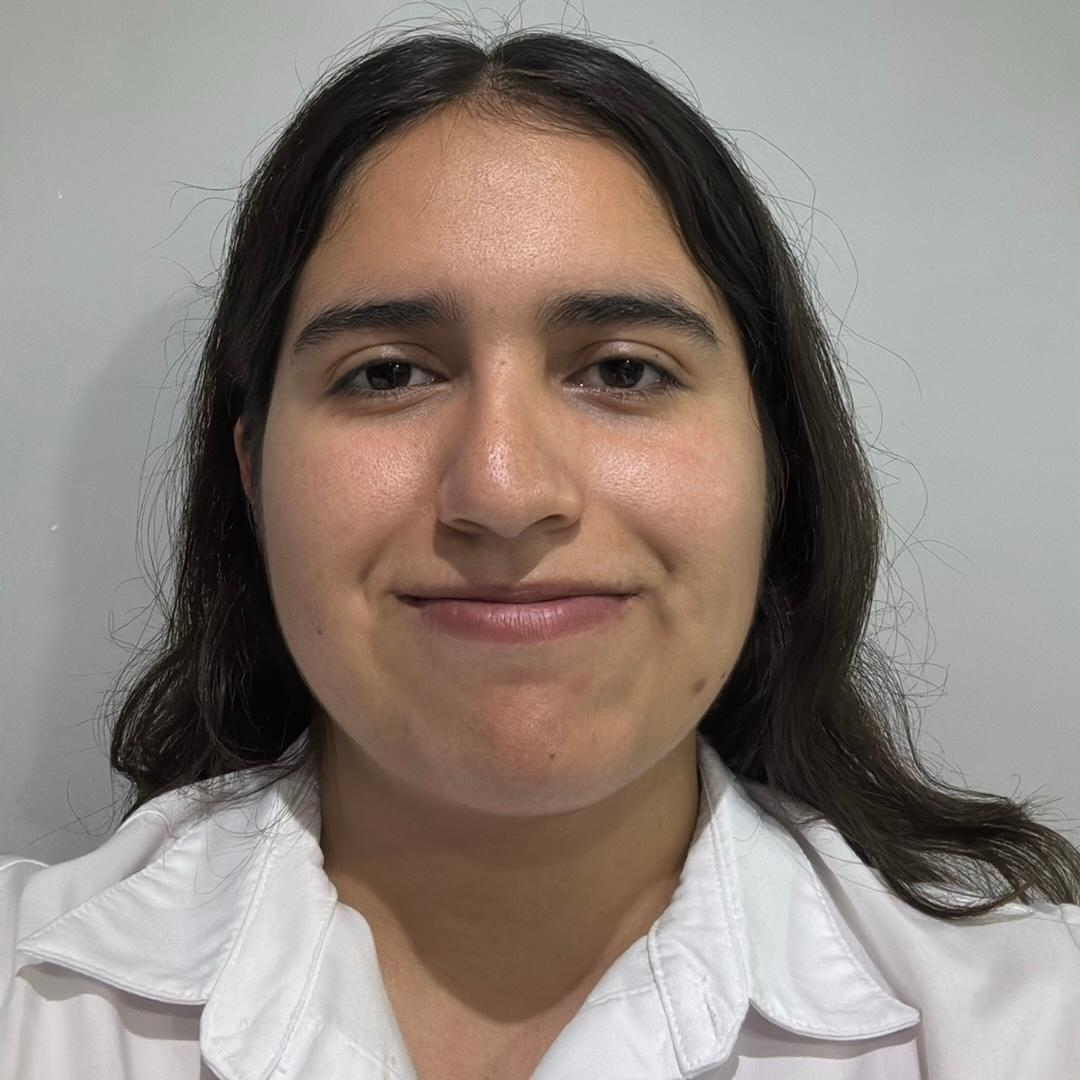

Nombre del alumno: **Anadalí Sifuentes Castro**

Número de control: **22212273**

Correo institucional: **L22212273@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Lazo abierto

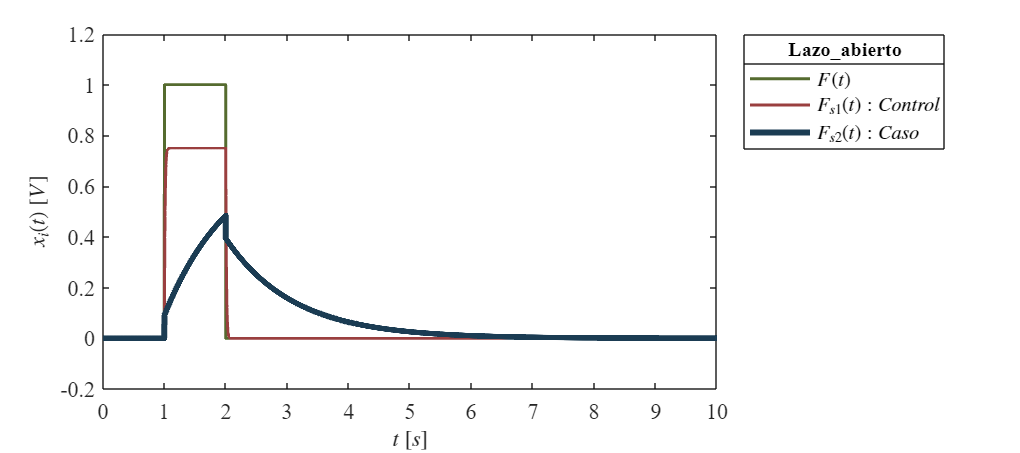

Signal = 'Lazo_abierto';
x = sim(file,parameters);
plotsignala(x.t,x.F,x.Fs1,x.Fs2,Signal)

## Lazo cerrado

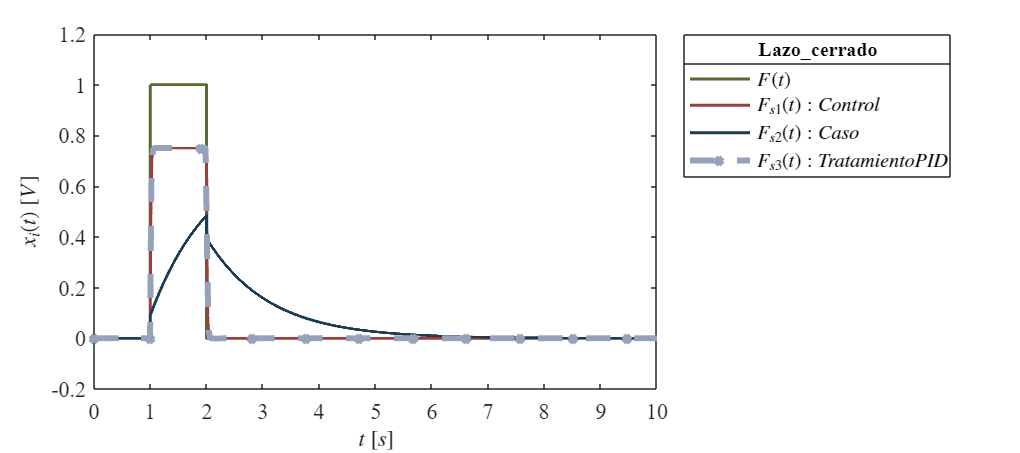

Signal = 'Lazo_cerrado';
x = sim(file,parameters);
plotsignalc(x.t,x.F,x.Fs1,x.Fs2,x.Fs3,Signal)

## Función: Respuesta a las señales

function plotsignala(t,F,Fs1,Fs2,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [85,107,47;
                154,63,63;
                27,60,83;
                152,161,188;
                51,56,160;
                249,122,0]/255;
    colororder(mycolors)
    
    
    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3);
    L = legend('$F(t)$','$F_{s1}(t): Control$','$F_{s2}(t): Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
    title(L,[Signal],'FontSize',10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,10]);xticks(0:1:10);
    ylim([-0.2,1.2]);yticks(-0.2:0.2:1.2);

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end


function plotsignalc(t,F,Fs1,Fs2,Fs3,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [85,107,47;
                154,63,63;
                27,60,83;
                152,161,188;
                51,56,160;
                249,122,0]/255;
    colororder(mycolors)
    
    
    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'--x',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(4),'LineWidth',3);
    L = legend('$F(t)$','$F_{s1}(t): Control$','$F_{s2}(t): Caso$','$F_{s3}(t): Tratamiento PID$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');
    title(L,[Signal],'FontSize',10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,10]);xticks(0:1:10);
    ylim([-0.2,1.2]);yticks(-0.2:0.2:1.2);


    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','Vector')
end
